# HW 3: Measurement and Analysis of Gait.  Part I

#### OVERVIEW:

In this homework, we will use motion capture data similar to what we have collected.  The goal is to get some intuition for what motion data looks like, including kinematics and ground reaction forces.  In HW 4 and HW 5, we will use some of this data to simulate an exoskeleton or prosthesis controller. Don't forget--there is a separate Word document for the Paper Analysis!

*TIP: To run a single cell, press Ctrl+Enter while the cell is selected (or cursor is in the cell).*

*TIP: On the side bar, just to the right of this, there are three icons showing options for how to display the output.  I prefer the middle icon, which prints/displays below the cell.*

*TIP: Make sure your "current folder" is the folder you downloaded with this script, and with the subfolder for the data. A shortcut to do this is to right click the tab of this cell ('HW3.mlx') and click "Change current folder to... "*

#### **Let's Begin:**

To start, run this cell that I have written to load the data file, which consists of all of the data we collected during a single trial, into an easy-to-use Table.  Inspect the head of the data table, which should have printed below this cell.  Note how each marker (e.g., "R_ASIS", which corresponded to the right Anterior Superior Iliac Spine (pointy hip bone)) has three columns, corresponding to the marker's X, Y, Z locations respectively.  Positive X = "rightward" on the treadmill. Positive Y = "forward" on the treadmill. Positive Z = "Upward."  Also note that COP has only two dimensions, corresponding to X (rightward) and Y (forward).  Finally, see the figure for locations of the markers

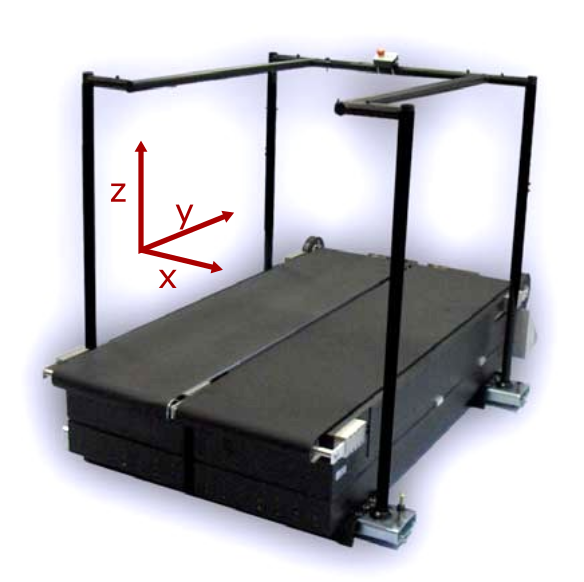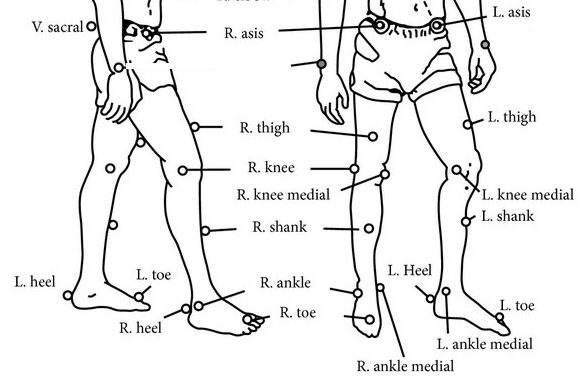

clear; close all; clc
addpath('HW3_data\', 'HW3_functions\')
filename  = "0deg_1.2ms_tracked"; % Load the intermediate walking speed trial

data = load(filename + ".mat");
temp_ = fieldnames(data);
data = data.(temp_{1});

fs_force    = data.Force.Frequency; % Forceplate sampling frequency
fs_markers  = data.FrameRate; % Marker sampling frequency
fs_delsys   = data.Analog(2).Frequency; % EMG sampling frequency

D   = RepackageMocapData(data, fs_force, fs_markers);
head(D) % Show the top 8 rows of the data table (D)

ans = 8×28 table
       Time                 R_ASIS                        L_ASIS                       V_Sacral                   R_Thigh_Front                   R_Knee_Lat                    R_Knee_Med                  R_Shank_Front                     R_Heel                     R_Ankle_Lat                   R_Ankle_Med                    R_Toe_Tip                   L_Thigh_Front                   L_Knee_Lat                    L_Knee_Med                  L_Shank_Front                     L_Heel                     L_Ankle_Lat                   L_Ankle_Med                    L_Toe_Tip                  R_COP               L_COP

## 1.a

Plot the anterior/posterior position of the right toe marker (D.R_Toe_Tip) vs time (D.Time). Zoom in to show approximately 3 strides. Update the code with that nifty "Update Code" button, so that if you run it from the beginning, you won't lose your zooming in.  Label your axes "Time (s)" and "Height (mm)".  [5 pts]

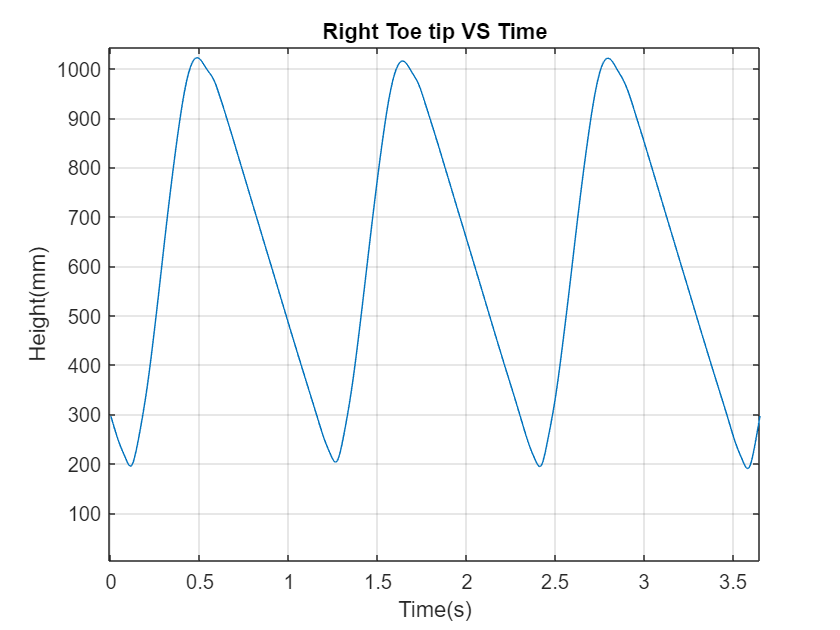

% Put your code here
% sign convention for the anatomical planes.
% X - rightward (+: Lateral; -: Medial)
% Y - forward (+: Anterior; -: Posterior)
% Z - Upward (+: Superior; -: Inferior)
x = D.Time;
y = D.R_Toe_Tip(:,2);
plot(x,y)
grid on,
% legend(["X", "Y", "Z"])
title('Right Toe tip VS Time')
xlabel('Time(s)')
ylabel('Height(mm)')

xlim([-0.01 3.65])
ylim([3 1044])

% legend('Position',[0.79643,0.80476,0.10714,0.11905])


## 1.b

Plot the 3D toe marker trajectories using the "plot3" command.  Label axes. Use the command "axis equal" to make spacing the same for all directions (in fact, you should do that for all plots showing spatial locations!). Rotate the view so that you can get an idea of what the toe trajectories were in space (roughly isometric view). Make sure to label axes, and add a legend. Again make sure to Update Code with your new view. [5]

*TIP: Use "hold on" to plot more than one thing per figure.*

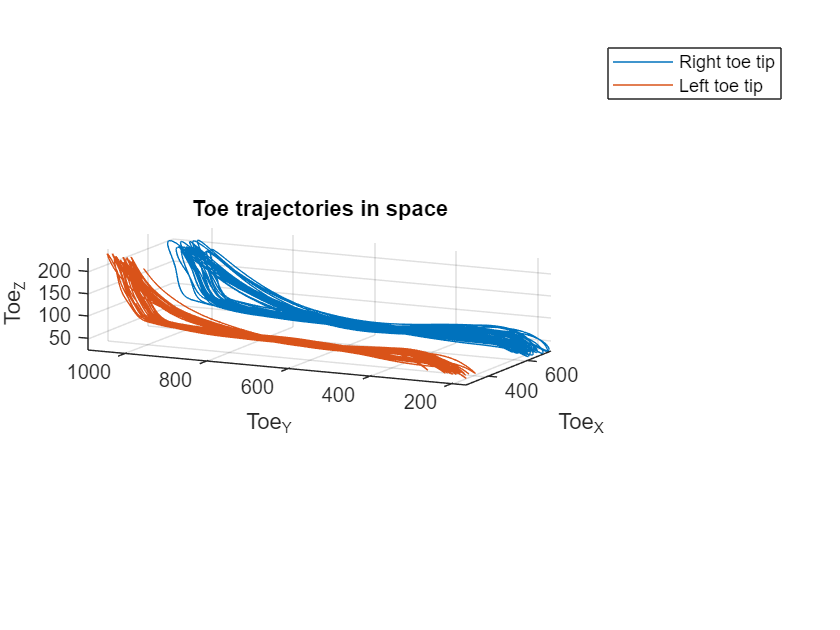

% Put your code here
x_1b_r=D.R_Toe_Tip(:,1);
y_1b_r=D.R_Toe_Tip(:,2);
z_1b_r=D.R_Toe_Tip(:,3);

x_1b_l=D.L_Toe_Tip(:,1);
y_1b_l=D.L_Toe_Tip(:,2);
z_1b_l=D.L_Toe_Tip(:,3);

plot3(x_1b_r,y_1b_r,z_1b_r,x_1b_l,y_1b_l,z_1b_l)
axis equal
xlabel('Toe_X')
ylabel('Toe_Y')
zlabel('Toe_Z')
grid on,
legend(["Right toe tip", "Left toe tip"])
title('Toe trajectories in space')

view([-64 11])

## 1.c

**Plot **the sagittal plane (Y-Z) trajectories of the *shank* (plot a line between the lateral ankle marker and lateral knee marker) and *foot* (plot a line between the heel marker and toe top) for approximately one stride (approximately the first 350 data points). Use a for loop!  Add axis labels, but no need for a legend in this plot. [5 pts]

*TIP: so that your computer doesn't slow down, I'd plot every 5th timestep. *

*TIP: if you add a short (0.01 s) pause in your for loop, Matlab will allow you to replay the plot as an animation!*

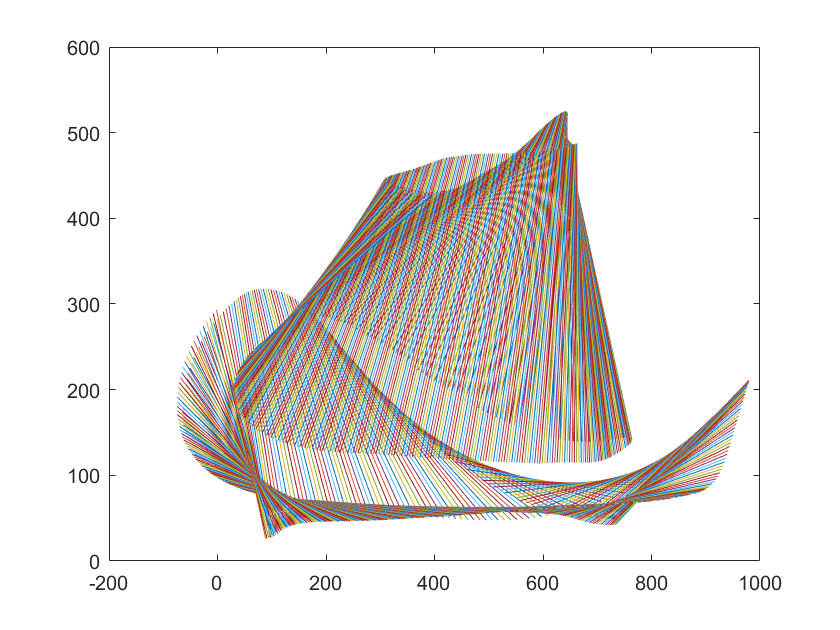

% Put your code here

d4=0; d3=d4; d2=d3; d1=d2;
for a=1:350 % a=1:5:350 would plot every 5th step.
%     y_1c_r_k=D.R_Knee_Lat(a,2);
%     y_1c_r_a=D.R_Ankle_Lat(a,2);
%     d1=line(y_1c_r_k,y_1c_r_a);

%     z_1c_r_k=D.R_Knee_Lat(a,3);
%     z_1c_r_a=D.R_Ankle_Lat(a,3);
%     d2=line(z_1c_r_k,z_1c_r_a);
% 
%     y_1c_r_h=D.R_Heel(a,2);
%     y_1c_r_t=D.R_Toe_Tip(a,2);
%     d3=line(y_1c_r_h,y_1c_r_t);
% 
%     z_1c_r_h=D.R_Heel(a,3);
%     z_1c_r_t=D.R_Toe_Tip(a,3);
%     d4=line(z_1c_r_h,z_1c_r_t);
% 
% %     z_1c_r_f=D.R_Heel(a,3);
% %     d4=[d4;z_1c_r_f];

% y_1c_r_k=D.R_Knee_Lat(:,2);
% y_1c_r_a=D.R_Ankle_Lat(:,2);
% d1=line(y_1c_r_k,y_1c_r_a);
% z_1c_r_k=D.R_Knee_Lat(:,3);
% z_1c_r_a=D.R_Ankle_Lat(:,3);
% d2=line(z_1c_r_k,z_1c_r_a);
% plot(d1,d2)
    
    plot([D.R_Ankle_Lat(a,2),D.R_Knee_Lat(a,2)],[D.R_Ankle_Lat(a,3),D.R_Knee_Lat(a,3)])
    hold on;
    plot([D.R_Heel(a,2),D.R_Toe_Tip(a,2)],[D.R_Heel(a,3),D.R_Toe_Tip(a,3)])
    pause(0.01);

end

## 2.a

An estimate of **sagittal plane** ankle kinematics can be obtained by calculating the angle between the following two lines: lateral ankle – lateral knee, and heel – toe.  

Edit the function “CalculateAnkleAngle” that takes in the data table D, and returns ankle angle, in degrees. Dorsiflexion (from neutral) should be positive, and ankle angle is typically defined as 0° when the foot segment is at a right angle to the shank segment, so make sure to add/subtract a 90 degrees offset angle if needed.  After you've edited the function, **run this cell** to display the ankle kinematics in a plot. Ankle range of motion should approximately -10 deg (plantarflexion) to 25 deg (dorsiflexion).  [10 pts]

*TIP: Use the atan2 function, as opposed to the atan function; atan2 keeps angle continuity around 90 deg.*

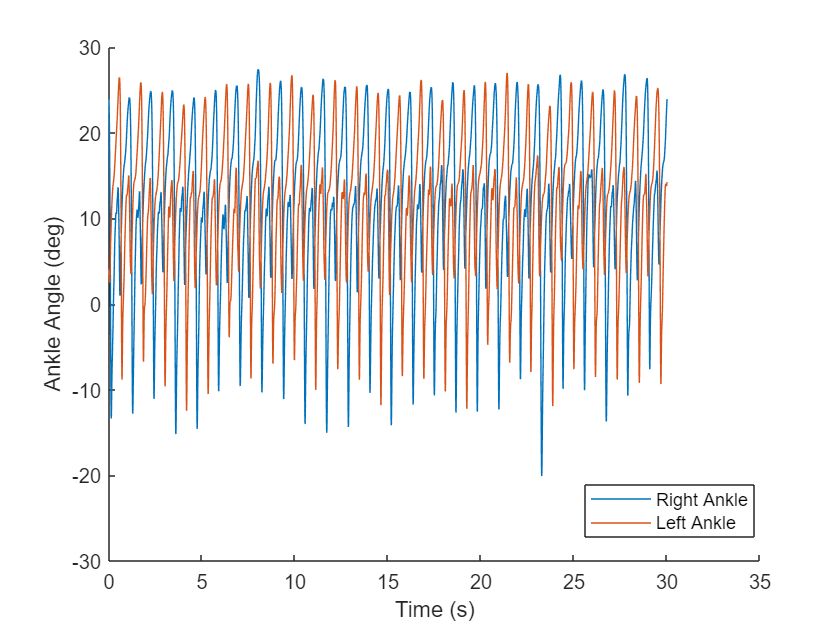

% Do not modify this code. Only modify the CalculateAnkleAngle function
R_Ankle_Angle = CalculateAnkleAngle(D.R_Knee_Lat, D.R_Ankle_Lat, D.R_Toe_Tip, D.R_Heel); 
L_Ankle_Angle = CalculateAnkleAngle(D.L_Knee_Lat, D.L_Ankle_Lat, D.L_Toe_Tip, D.L_Heel);
figure; hold on
plot(D.Time, R_Ankle_Angle)
plot(D.Time, L_Ankle_Angle)
xlabel('Time (s)')
ylabel('Ankle Angle (deg)')
legend(["Right Ankle","Left Ankle"])

legend('Position',[0.69702,0.14802,0.20179,0.08373])

## 2.c

Modify "CalculateJointVelocity" to calculate angular velocity from joint angle data using Matlab’s “diff” function and the known sampling frequency.  Use the filter flag "do_filter", such that when True, the function filters the velocity data with a 4th order, 10 Hz, zero-lag low-pass butterworth filter using “filtfilt.”  Reminder: I discuss filtering in the lecture notes. 

**Make a plot **comparing ankle velocity of the Right Ankle Angle when filtered vs unfiltered. Zoom in to approximately three strides. [10 pts]

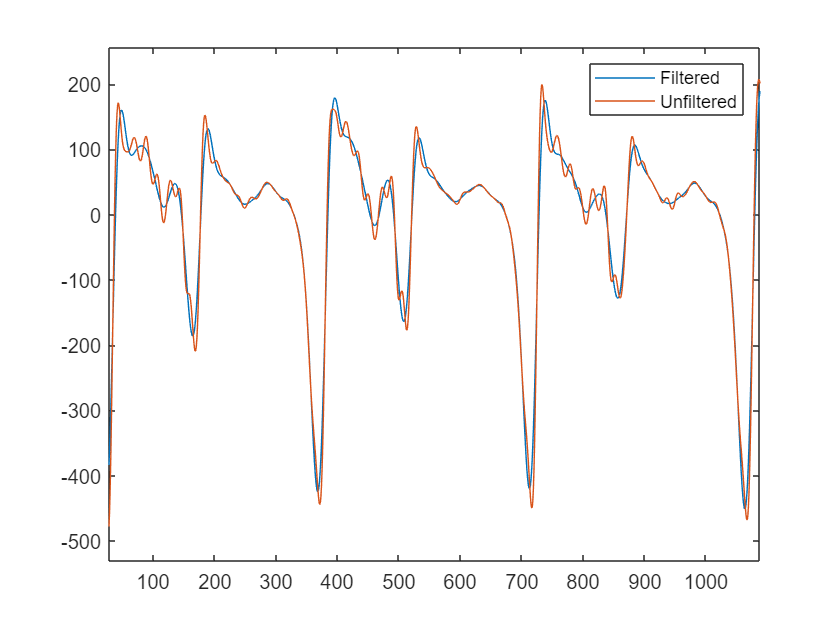

% Put your code here
R_Ankle_angvel_fil = CalculateJointVelocity(R_Ankle_Angle, 300, true);
R_Ankle_angvel = CalculateJointVelocity(R_Ankle_Angle, 300, false);

figure
% a= size(D.Time);
plot(R_Ankle_angvel_fil);
hold on
plot(R_Ankle_angvel);
legend(["Filtered","Unfiltered"])

xlim([28 1088])
ylim([-531 257])

## 3.a

Plot the right treadmill belt's vertical ground reaction force vs Time and the anterior/posterior ground reaction force vs Time (on the same plot.)  *Note*: Treadmill force is in N.  Zoom into approximately three strides. Don't forget to label axes and add a legend [5 pts]

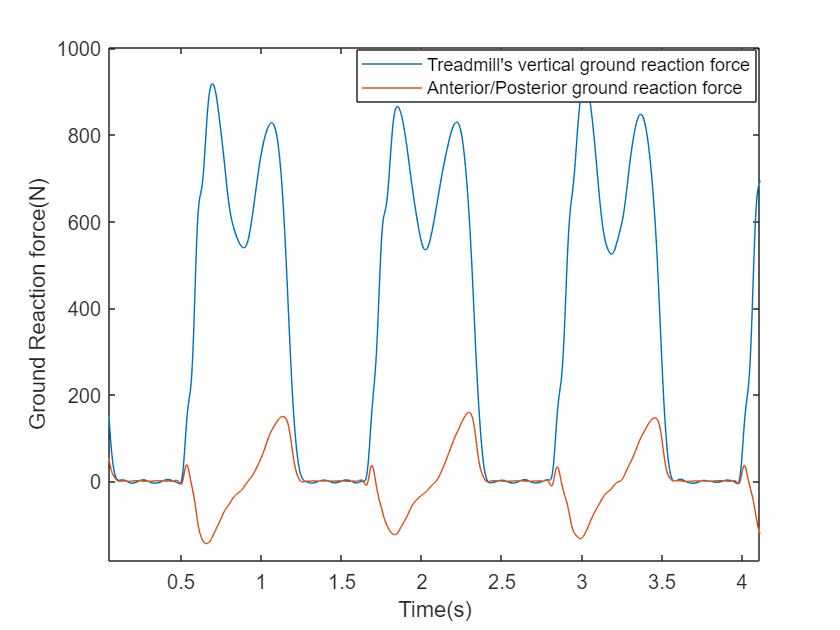

% Put your code here
z_3a=D.R_F(:,3);
y_3a=D.R_F(:,2);

figure
plot(D.Time,z_3a)
hold on
plot(D.Time,y_3a)
legend(["Treadmill's vertical ground reaction force", "Anterior/Posterior ground reaction force"])
xlabel('Time(s)')
ylabel("Ground Reaction force(N)")

xlim([0.05 4.11])
ylim([-184 1003])
legend('Position',[0.4248,0.83902,0.47679,0.082143])

## **3.b**

This is just for fun; nothing to do here. **Run this cell** to generate a figure of the GRF vector relative to the ankle. 

Note: *COP_relative_to_ankle_in_AP* describes where the center of pressure is relative to the ankle axis (as defined by the ankle marker), in the anterior-posterior direction. We will use this variable in the next cell to calculate ankle torque.  [0]

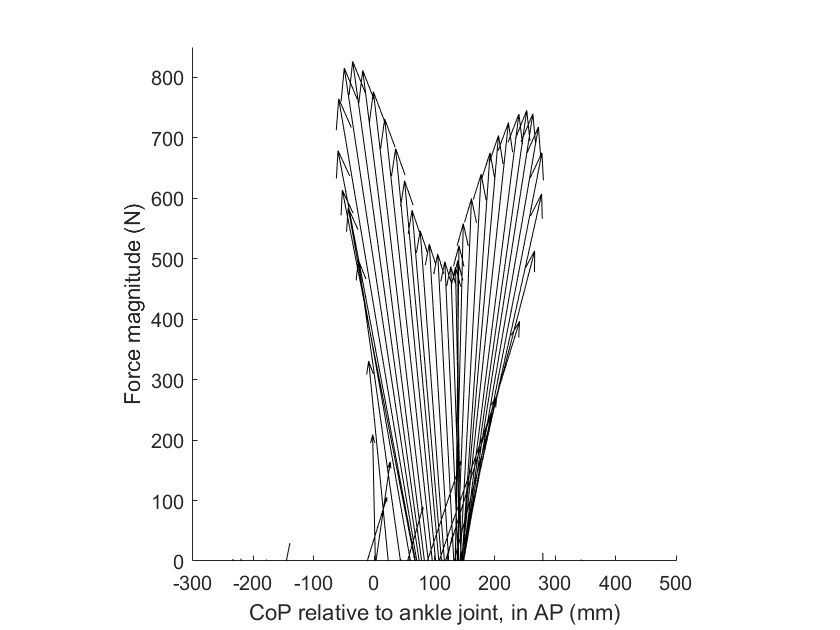

% Do not modify this cell
COP_relative_to_ankle_in_AP = D.R_COP(:,2) - D.R_Ankle_Lat(:,2);
figure; hold on
axis equal
xlabel('CoP relative to ankle joint, in AP (mm)')
ylabel('Force magnitude (N)')
xlim([-300,500])
ylim([0,850])
for i = 50:5:400
    quiver(COP_relative_to_ankle_in_AP(i), 0, D.R_F(i,2), D.R_F(i,3), 'k')
    pause(0.01)
end    

## 3.c

The ankle torque can be determined by considering the force applied to the foot segment.  We will make a couple simplifications: 1) ignore medial/lateral motions, and use only the **sagittal plane kinematics and GRFs**, 2) ignore foot mass and inertia in this calculation. Use both the vertical and horizontal components of the GRF, as well as the moment arms between ankle location and force vector location.  

**Edit the function** CalculateAnkleTorque to take in the forces and moment arms, and return ankle torque. Then, run this cell to plot ankle torque for the right ankle. [10 pts]

*Note*: center of pressure is only defined when a force exists (i.e. when force is non-zero), but we still have small, stray numbers for the COP during swing.  Use a threshold on vertical GRF of 50 N such that during swing phase, ankle torque is defined as 0. 

*Note 2:* One of the confusing things about this type of analysis is the sign conventions.  The GRF is applying an EXTERNAL moment about the ankle joint.  But we are interested in the INTERNAL ankle moment--that is, the moment created by our muscles pulling.  The INTERNAL moment is equal and opposite to the EXTERNAL moment in this static case. We're going to call an **internal** **dorsiflexion** **torque positive** (the red arrow is showing the INTERNAL moment.)

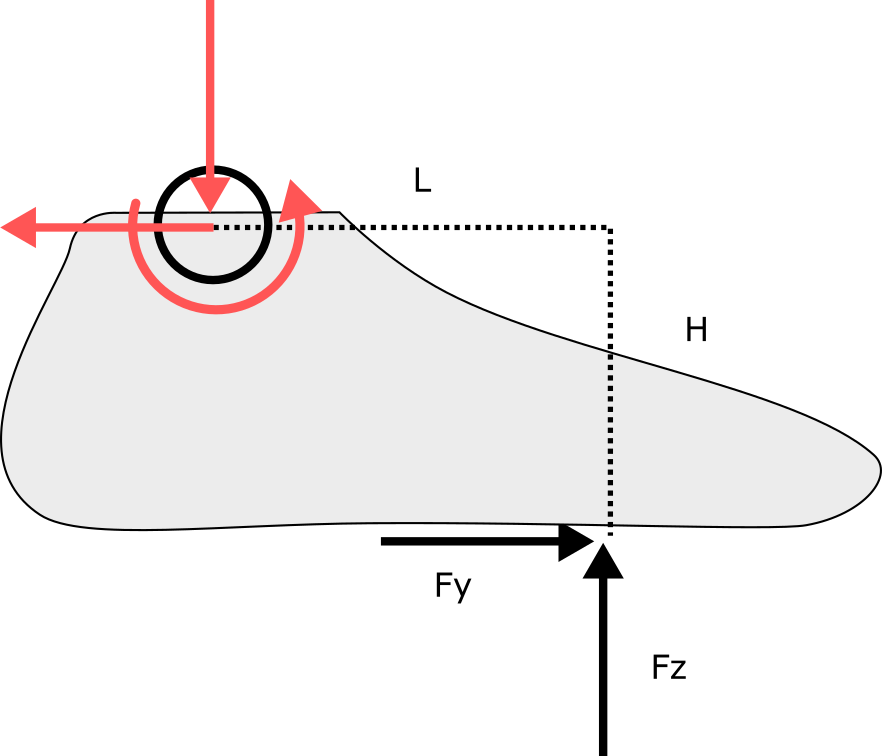

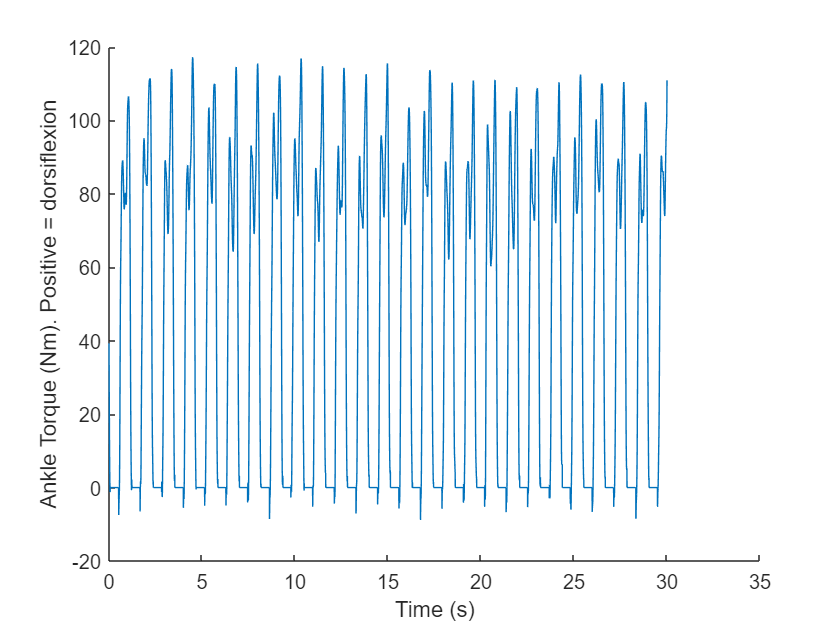

% Do not modify code; only modify CalculateAnkleTorque
mm_to_m = 0.001; % Markers are in mm but we need them in standard metric units (m)
R_Ankle_Torque = CalculateAnkleTorque(D.R_F(:, 2), D.R_F(:,3), COP_relative_to_ankle_in_AP*mm_to_m, D.R_Ankle_Lat(:,3)*mm_to_m);
R_Ankle_Torque(D.R_F(:,3)<50) = 0;

figure; hold on
plot(D.Time, R_Ankle_Torque)
ylabel('Ankle Torque (Nm). Positive = dorsiflexion')
xlabel('Time (s)')

## 3.d

Why were the assumptions we made reasonable for the ankle, but not the knee? What is a task for which this would not have been a reasonable assumption at the ankle? [5]  

*Your Answer Here*

- There a numerous muscles near the knee that exert forces and assist the knee in following a guided path during walking. This motion occurs in all the 3 directions. Hence, considering the forces only in the sagital plane would not have been a reasonable assumption. Also for the ankle, it was easier to flip the direction of the GRF to find the internal force/moment. This would also not be a reasonable assumption for the knee.

- The assumptions made for the ankle would not be reasonable for any task that does not follow the normal gait like running, walking on a hill or any different terrain. If we consider the case of models walking on the ramp (catwalk), alot of conscious efforts are put by them to keep the foot placement in a single line. In this case it would be important to consider the medial/lateral motions.

## 3.X

Calculate and plot Ankle Power in Watts (make a new figure).  Zoom in to show three strides.  [5]

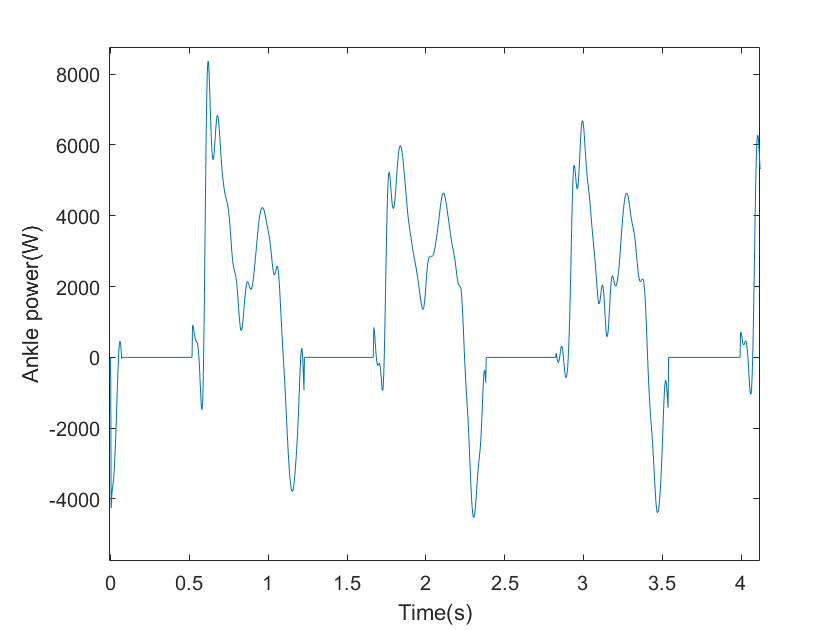

% Put your code here
R_Ankle_Power = R_Ankle_Torque.* [0 R_Ankle_angvel']';
figure
plot(D.Time, R_Ankle_Power)
xlabel('Time(s)')
ylabel('Ankle power(W)')

xlim([-0.01 4.12])
ylim([-5751 8763])

## 4.a

Modify "GetHeelStrikes.m" to calculate heel strike indices using a threshold of 50 N on vertical force.  The function should return a vector containing the indices at which heel strike occurred.  Similarly, modify "GetToeOffs.m" to calculate toe offs using the same threshold value. Then **run this cell**, which will plot your heel strike and toe off indices relative to the vertical ground reaction force. Zoom in if it helps you debug! [5 pts]

*Hint: heel strike occurs if the vertical force was previously not above the threshold, but is now... *

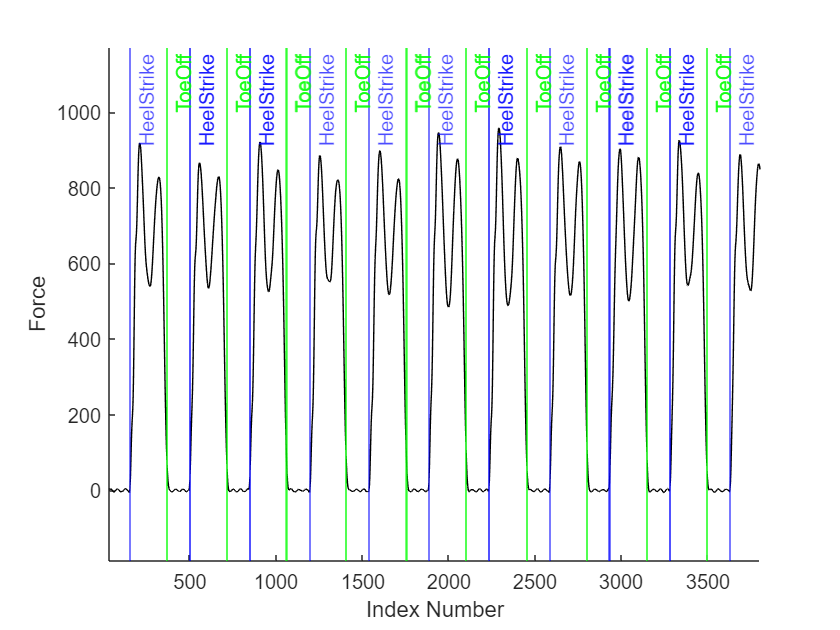

% Do not modify this cell
R_HeelStrikes   = GetHeelStrikes(D.R_F(:, 3));
R_ToeOffs       = GetToeOffs(D.R_F(:, 3));
figure; hold on
xline(R_HeelStrikes,'b',{'HeelStrike'})
xline(R_ToeOffs,'g',{'ToeOff'})
plot(D.R_F(:,3),'k')
ylabel('Force')
xlabel('Index Number')

xlim([31 3803])
ylim([-187 1172])


%For 3 strides
% xlim([24 1266])
% ylim([-136 1174])

## 4.b

**Edit the function** ('SegmentDataByPhase'), that segments strides by heel strike.  Warning, this part can be a bit confusing! Take your time, and make use of the debug tool if you need to.  

The function should take two inputs: 1) a list containing heel strike indices, and 3) the data you want to segment. It should have one output: a 101 x n matrix, where n is the number of strides. Each stride (heel strike to the following heel strike) gets its own column, and has been interpolated to be 101 datapoints, corresponding to the percentage of stride [0:1:100].  **Execute the cell** below to plot the individual heel strike trials, and the average profile.  [15]

Hint: you will want to make use of the *interp1* function, as discussed in class!

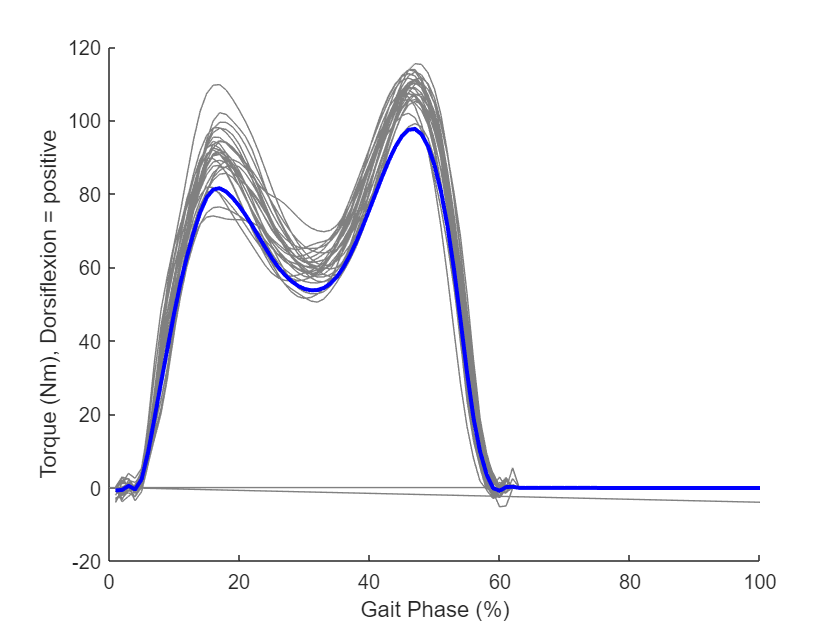

% Do not modify this cell
% If your function "SegmentDataByPhase" is working properly, this cell will
% plot the 25 strides of ankle torque.
gait_phase = 0:1:100;

r_ankle_angles = SegmentDataByPhase(R_HeelStrikes, R_Ankle_Angle);
r_ankle_torques = SegmentDataByPhase(R_HeelStrikes, R_Ankle_Torque);
mean_r_ankle_angle = mean(r_ankle_angles, 2);
mean_r_ankle_torque = mean(r_ankle_torques, 2);

figure; hold on
plot(gait_phase, r_ankle_torques, 'color', [0.5, 0.5, 0.5, 0.5])
plot(gait_phase, mean_r_ankle_torque, 'b', linewidth = 2)
ylabel('Torque (Nm), Dorsiflexion = positive')
xlabel('Gait Phase (%)')

## 4.c

**Plot** the mean ankle angle vs mean ankle torque. In this case, define dorsiflexion *angle* as positive, and plantarflexion *torque* as positive (i.e., multiple your mean ankle torque by -1). One reason we often do this is because the ankle behavior during gait is spring-like. To illustrate this, we have to describe the EXTERNAL moment (again, equal and opposite) that would cause the spring to deflect.  So this illustrates how, as the ankle is dorsiflexed, it resists with a plantarflexion torque. [5]

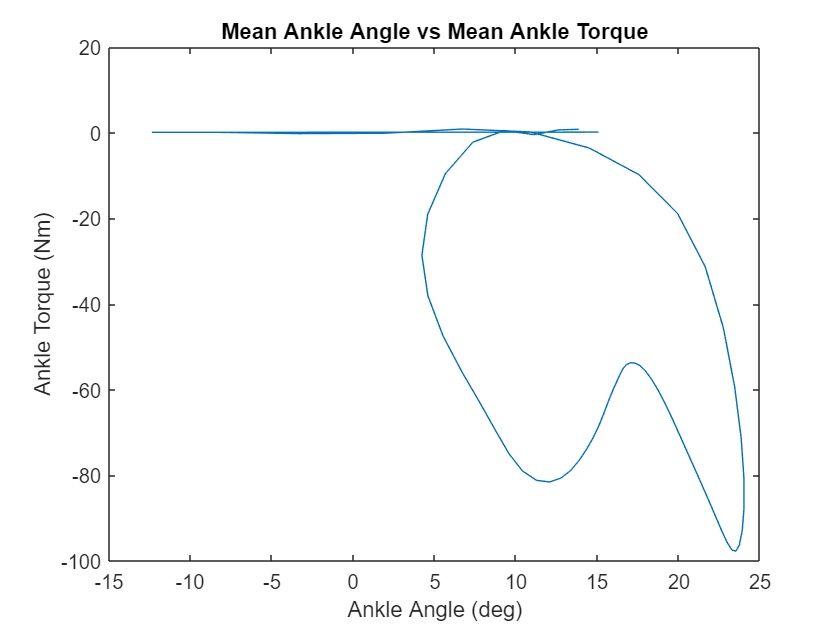

% Put your code here
ankleAngle = r_ankle_angles; 
ankleTorque = r_ankle_torques;
meanAnkleAngle = mean(ankleAngle, 2);
meanAnkleTorque = mean(ankleTorque, 2);
meanAnkleTorque = -1 * meanAnkleTorque;
figure
plot(meanAnkleAngle, meanAnkleTorque);
xlabel('Ankle Angle (deg)');
ylabel('Ankle Torque (Nm)');
title('Mean Ankle Angle vs Mean Ankle Torque');

## 4.d

Finally, **run the following cell**, which sequentially loads and plots the slow, medium, and fast trials. **Answer the remaining question below**.

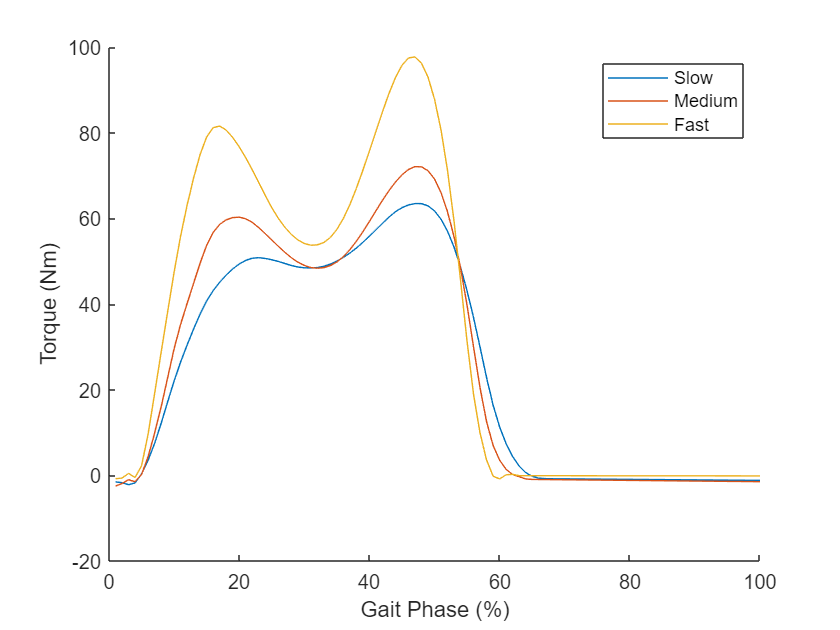

close all
filename  = ["0deg_.9ms_tracked", "0deg_1.2ms_tracked", "0deg_1.5ms_tracked"]; % Load the intermediate walking speed trial
for file_num = 1:3
    data = load(filename(file_num) + ".mat");
    temp_ = fieldnames(data);
    data = data.(temp_{1});
    fs_force    = data.Force.Frequency; % Forceplate sampling frequency
    fs_markers  = data.FrameRate; % Marker sampling frequency
    
    D   = RepackageMocapData(data, fs_force, fs_markers);

    R_Ankle_Angle = CalculateAnkleAngle(D.R_Knee_Lat, D.R_Ankle_Lat, D.R_Toe_Tip, D.R_Heel); % Only modify CalculateAnkleAngle function
    COP_relative_to_ankle_in_AP = D.R_COP(:,2) - D.R_Ankle_Lat(:,2);
    R_Ankle_Torque = CalculateAnkleTorque(D.R_F(:, 2), D.R_F(:,3), COP_relative_to_ankle_in_AP*0.001, D.R_Ankle_Lat(:,3)*0.001);
    R_Ankle_Torque(D.R_F(:,3)<50) = 0;
    R_HeelStrikes   = GetHeelStrikes(D.R_F(:, 3));
    
    gait_phase = 0:1:100;
    
    r_ankle_torques = SegmentDataByPhase(R_HeelStrikes, R_Ankle_Torque);
    mean_r_ankle_torque = mean(r_ankle_torques, 2);
    
    figure(1); hold on
    plot(gait_phase, mean_r_ankle_torque)
end
legend(["Slow", "Medium", "Fast"])
ylabel('Torque (Nm)')
xlabel('Gait Phase (%)')

## **5.a**

**Why might the ankle torque be increasing with increasing speed?**  [5*]

*Your answer here*

As seen above, ankle torque depends on the ground reaction forces. When we walk faster, the force with which the heel strikes increases. The increase in the GRF increases the pulling forces of the muscles and this leads to an increase in ankle torque.The forces pushing on the ankles start to grow as the step frequency does, which results in an increase in ankle torque. The increased muscle forces cause the dorsiflexion and plantarflexion angles to increase.

In a study it was also found tha: The contribution of **tendon elastic strain energy** to positive work in the ankle plantar flexors increased significantly with increase speed. The muscle forces cause the elastic strain on the tendons. Under extreme cases, running at high speeds could damage the tendon

## 5.b

**How might you adapt a prosthesis or exoskeleton controller to change with speed?** [5*]

*Your answer here*

I had explained a similar example in the previous homework. But I feel the best controller would be the one which gives the user enough flexibility to control the speed based on the external factors. Using a few feedback sensors over it would help the designer understand the muscle motion and conduct further experiments. The controller should be able to learn from the different movements of the user.

## To turn in the homework:

Don't forget the paper analysis! This is in a separate Word Doc, and is a separate "Assignment" on canvas. 

Make sure all plots are visible (re-run your code if you have to, but don't forget to zoom into the figures if you need to). Save this matlab file as a pdf.  **Upload this pdf to the Assignment: "HW 3 Part I: Working with Biomechanics Data."**

Next, upload your Paper analysis to "HW 3 Part II: Paper Analysis"

Finally, upload a zip folder containing your Matlab scripts (will help us debug if there were issues) to "HW 3 upload Matlab Files here"